# Extracting BPSK signal from a noisy observation:

gaussian_noise = normrnd(0,1,[1 1000]); 
r = rand([1, 1000]); 
bpsk = (r >= 0.5)*1 + (r < 0.5)*(-1);
bpsk_received = bpsk+gaussian_noise; 

## Using LMSE criterion, exract bpsk:

- Optimal solution

bpsk_prediction = sign(tanh(bpsk_received));
error = bpsk - bpsk_prediction

error =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -2     0     0     0     0     0     0     2     0     0     0     0     0     0     2     0     0     0     0     0     2    -2     0     0     0     0     2    -2    -2


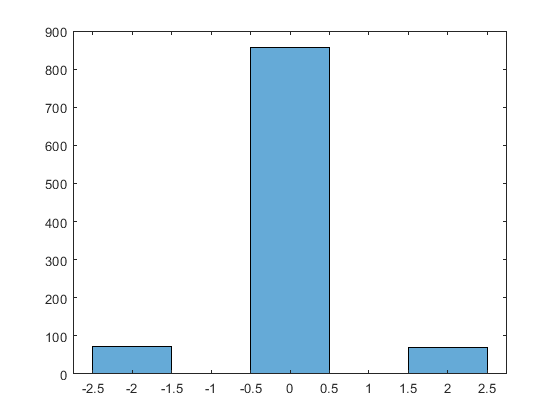

histogram(error)

cost = sum(error.^2)

cost = 572

- Suboptimal/hard solution

bpsk_suboptimal = sign(bpsk_received);
e_suboptimal = bpsk - bpsk_suboptimal;
histogram(e_suboptimal)

c_suboptimal = sum(e_suboptimal.^2)

c_suboptimal = 572

## Comparision between optimal and suboptimal

fr = c_suboptimal/cost; 

"Error rate is "+ fr + " times the optimal solution when using suboptimal estimator"

ans = "Error rate is 1 times the optimal solution when using suboptimal estimator"

Hence we conclude that both function's performance match.